session_number=73

session_number = 109

extr

fscv chs 1  2  3  4


chnl=4



[axaR,tridsR,dataR]=tr_raster(trlists,'fscv','da',chnl,'ttypes',{{'big','small'},{'post','reward'}},'win',[-12,4],'event','display_fix');
datamean=nanmean(data,1);
datase=nanstd(data,0,1)./sqrt(size(data,1));
datameanR=nanmean(dataR,1);
dataseR=nanstd(dataR,0,1)./sqrt(size(dataR,1));

titles="Session 73, Site C53"

titles = "Session 73, Site C53"

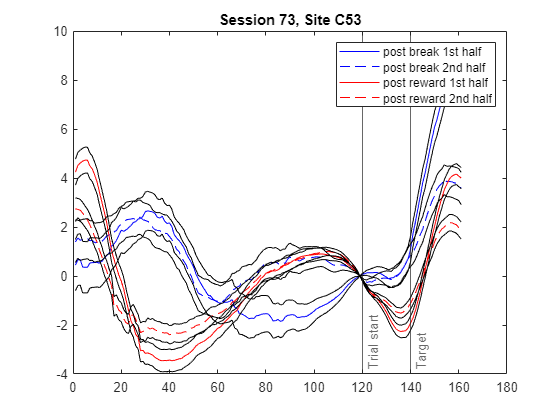

n=round(.5*size(data,1));
firsthalfsesh_PB = data(1:n,:);
secondhalfsesh_PB = data(n+1:end,:);
n1=round(.5*size(dataR,1));
firsthalfsesh_REW = dataR(1:n1,:);
secondhalfsesh_REW = dataR(n1+1:end,:);
firsthalfsesh_PBmean=nanmean(firsthalfsesh_PB,1);
firsthalfsesh_PBse=nanstd(firsthalfsesh_PB,0,1)./sqrt(size(firsthalfsesh_PB,1));
firsthalfsesh_REWmean=nanmean(firsthalfsesh_REW,1);
firsthalfsesh_REWse=nanstd(firsthalfsesh_REW,0,1)./sqrt(size(firsthalfsesh_REW,1));
secondhalfsesh_PBmean=nanmean(secondhalfsesh_PB,1);
secondhalfsesh_PBse=nanstd(secondhalfsesh_PB,0,1)./sqrt(size(secondhalfsesh_PB,1));
secondhalfsesh_REWmean=nanmean(secondhalfsesh_REW,1);
secondhalfsesh_REWse=nanstd(secondhalfsesh_REW,0,1)./sqrt(size(secondhalfsesh_REW,1));
figure; plot(firsthalfsesh_PBmean,'-b')
hold on; plot(secondhalfsesh_PBmean,'--b')
hold on; plot(firsthalfsesh_REWmean,'-r')
hold on; plot(secondhalfsesh_REWmean,'--r')
hold on; plot(firsthalfsesh_PBmean+firsthalfsesh_PBse,'-k')
hold on; plot(firsthalfsesh_PBmean-firsthalfsesh_PBse,'-k')
hold on; plot(secondhalfsesh_PBmean+secondhalfsesh_PBse,'-k')
hold on; plot(secondhalfsesh_PBmean-secondhalfsesh_PBse,'-k')
hold on; plot(firsthalfsesh_REWmean+firsthalfsesh_REWse,'-k')
hold on; plot(firsthalfsesh_REWmean-firsthalfsesh_REWse,'-k')
hold on; plot(secondhalfsesh_REWmean+secondhalfsesh_REWse,'-k')
hold on; plot(secondhalfsesh_REWmean-secondhalfsesh_REWse,'-k')
title(titles)
x3=xline(120,'-',{'Trial start'});
x3.LabelVerticalAlignment = 'bottom';
x2=xline(140,'-',{'Target'});
x2.LabelVerticalAlignment = 'bottom';
legend("post break 1st half", "post break 2nd half","post reward 1st half", "post reward 2nd half")